# Building a Simple Filtering App

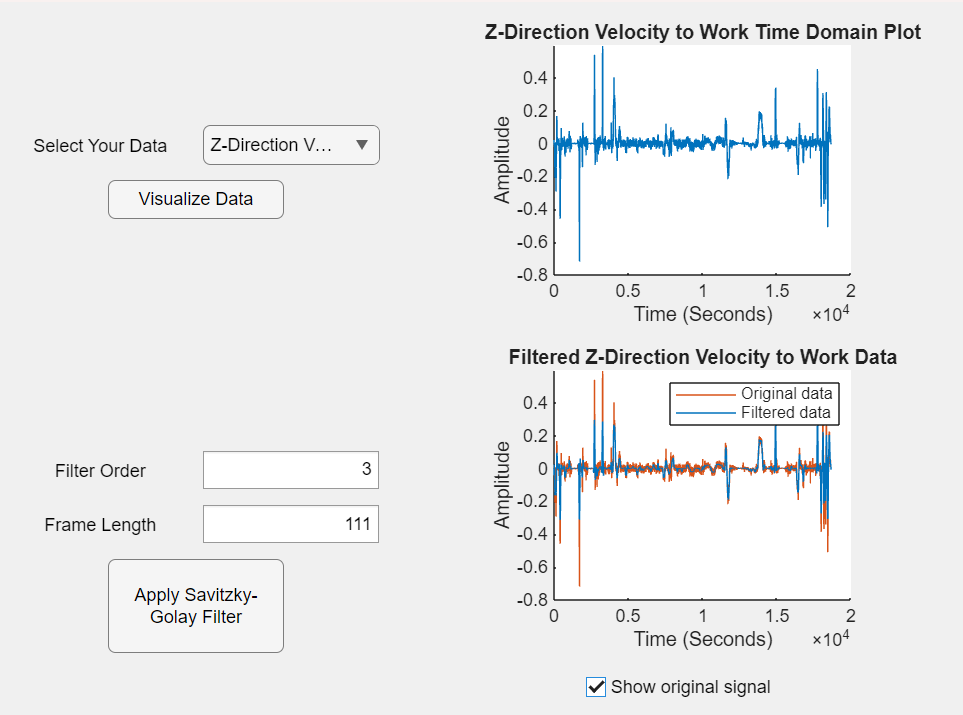

## Before you get started

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB® Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

   For a more detailed overview of using App Designer, you can take the free 1 hour [App Building Onramp](https://matlabacademy.mathworks.com/details/app-building-onramp/orab).

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

## Open App Designer

Use the following button to open App Designer:

 
appdesigner

Once App Designer opens, select "Blank App" as shown in the following screenshot:

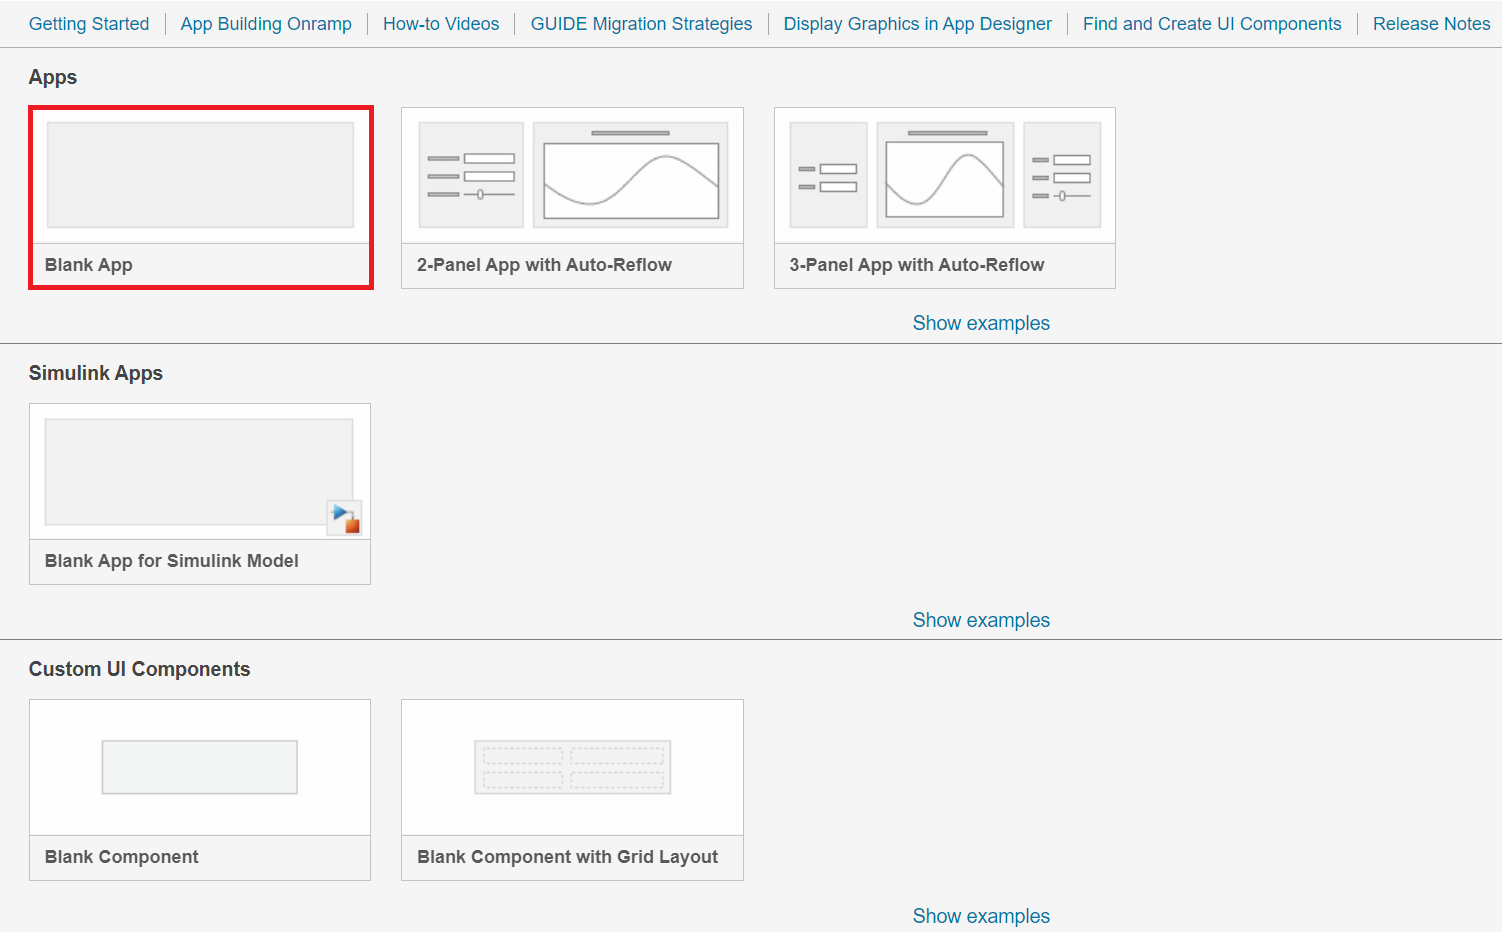

## Add Components

Now that you've created your app, it's time to give it some components!

**Step 1:** Add an Axes component to the app canvas. This is where your signals will be visualized.

In the Component Library, which should be on the left side of your screen, click and drag an Axes object onto the blank canvas. The Axes object should be in the "Common" section of the Component Library, but if you are unable to find it, you can also find it using the Search bar. The icon will look like the following:

**Step 2: **Add a Drop Down component to the app. This will be used to select which signal to visualize.

Add a Drop Down object by clicking and dragging it from the Component Library, just like for the Axes object. Place the Drop Down object next to the Axes object. The icon will look like the following:

**Step 3: **Add a Button component to allow the user to visualize the signal.

Just like you did for the Axes and Drop Down objects, click and drag a Button from the Component Library onto the canvas. The icon will look like the following:

## Save Your Work!

Before you go any farther, make sure that you have saved your work. Save your app as `MyFilteringApp.mlapp` in the `Apps` folder. In Design View, your app should look something like this:

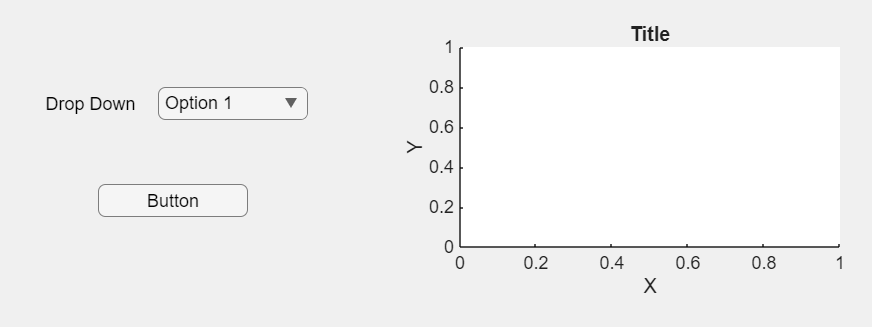

## Edit Components

These components look great, but it's not clear what they do. Let's customize them to fit their purposes.

### The Axes

First, let's give the axes a title. To do this, click on the Axes object on the canvas, then look at the Component Browser on the right side of the screen. You will see a field called "Title.String"; edit it to something like "No Data Selected". This title will change depending what is plotted on the axes; this is just a default title until something has been plotted. If you would like to change the default labels for the X and Y axes as well, feel free to do so.

### The Drop Down

Let's start by giving the drop down a label that describes what it does. You can do this the same way you changed the axes labels - simply double click on the current label and change it to say "Select Your Data". Note that this will also change the name of the component to `app.SelectYourDataDropDown`.

The drop down also needs real options for the user to choose from. To keep the app simple for now, let's just provide two options: the two accelerometer signals measuring z-axis velocity that you saw in [FilteringIntro.mlx](matlab:open('./FilteringIntro.mlx')). To do this, select the drop down object on the canvas by clicking on it; it should appear in the Component Browser on the right side of your screen as seen in the image below:

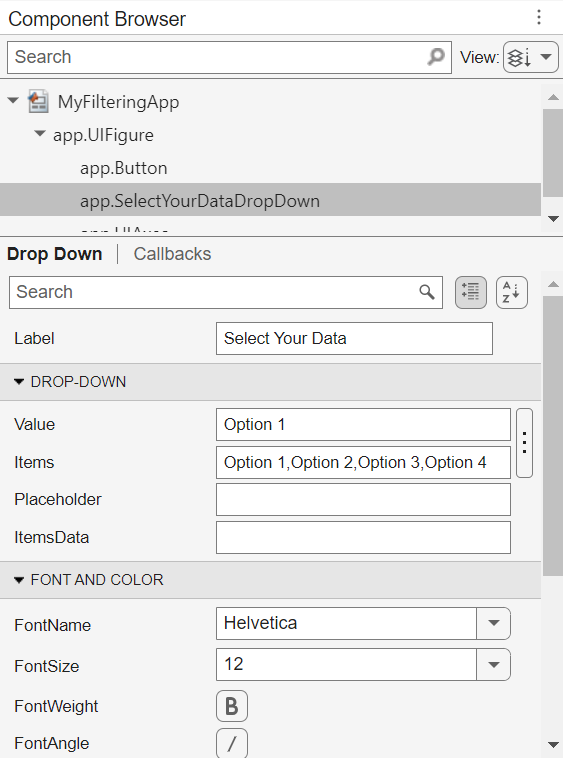

In the "Items" text box, enter the following options ("None" will be the default):

- None

- Z-Direction Velocity (Commute to Work)

- Z-Direction Velocity (Commute Home)

Then, in the "ItemsData" text box, enter the following items to correspond with the options above (these will be shorter because the user will never see them, they will only be used in the code):

- None

- Work

- Home

Now your drop down will provide the user with these three choices!

### The Button

Finally, let's give the button a name that describes what it does. To do this, double click on the button and edit the text to say "Visualize Data". This will automatically rename the component to `app.VisualizeDataButton`.

## Load the Data

### Create Properties

In order for the user to select their data using the drop down you created, the app needs to have access to the data. To achieve this, you'll need to create *properties*. Properties are variables in the app that will be visible to every function. To create properties, first enter "Code View" using the toggle above the app canvas. Now, in the toolstrip at the top of the screen, you should see a button that says "Property" in the "Insert" section as shown below:

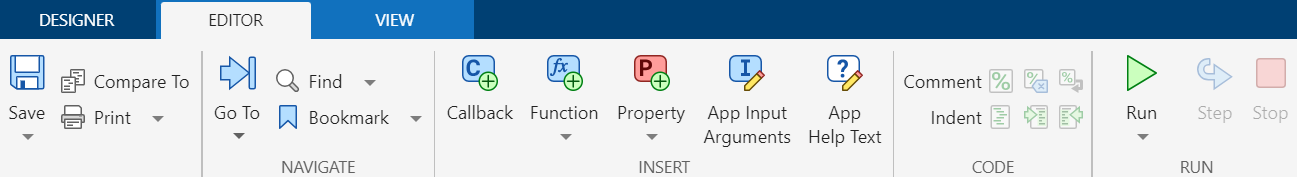

When you click this button, you should see a new section of code appear like this:

Now, you'll need to replace this placeholder line of code with the following lines, which will create variables in which you can store the data:

The `CommuteHome` and `CommuteToWork` properties will store the two signals. The `SamplingFrequency` property is set to 10Hz because that is the rate at which both signals were sampled. The `CurrentData` property will allow the app to keep track of which data is currently selected, while the `CurrentDataName` property will be used to contain the name of the currently selected data.

### Add a Callback

In App Designer, user interaction is coded with functions called "Callbacks". When a user interacts with the app in a specified way, a callback function will execute. Let's create a callback that will load in the data when the app is loaded.

To create a callback from Code View, click the "Callback" button in the "Insert" section of the toolstrip as shown below:

You should see a dialog pop up; click the "Component" drop down and select "MyFilteringApp" (or whatever name you chose for your app). The "Callback" drop down should be set to "StartupFcn", which means that this callback will execute every time the app is started up. You can keep the default name for the callback, so the dialog should look like this:

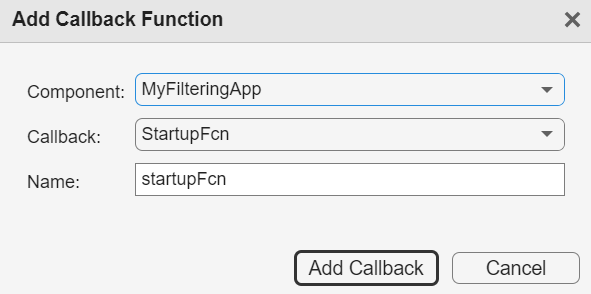

Then, you can click "Add Callback". You should see a new block of code appear that looks like this:

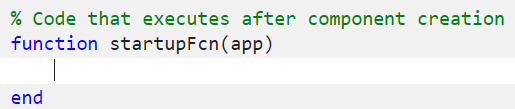

Copy and paste the following code into the callback function to load the data when the app is loaded:

*Note: Make sure that the project *`DSP.prj`* is loaded before you try running the app later on. If it is not, the data may not be on the MATLAB path and the app will not be able to load it.*

## Design the Functionality

### Add a Callback for the Drop Down

For the app to have all of the desired functionality, it will need a few more callbacks. You can set up a callback on a specific component of the app from Design View by right-clicking on the component and selecting "Callbacks" $\rightarrow$ "Add <type of callback> callback" from the context menu. For the drop down, that will look something like:

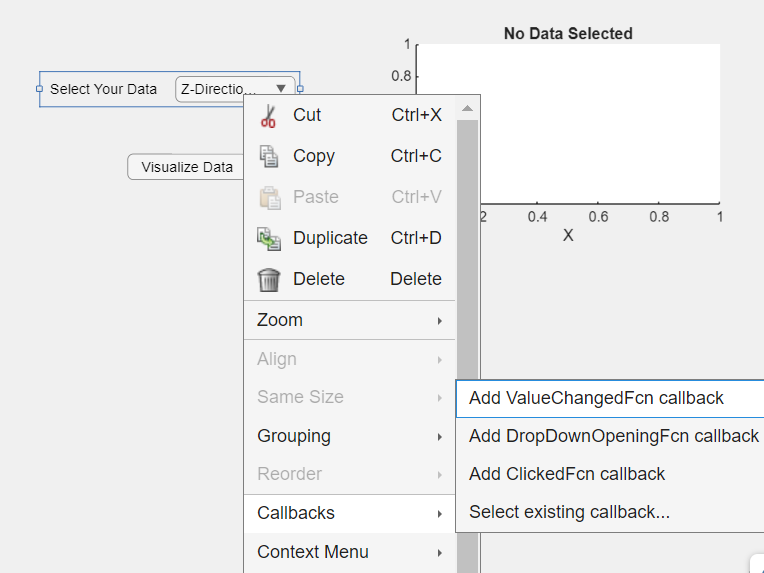

For this callback, you should select "Add ValueChangedFcn callback", as this is the one that will execute when the user changes the value of the drop down. When you click "Add ValueChangedFcn callback", you will automatically be switched to Code View. You should see a new block of code appear, just like you did when you created the previous callback. You'll notice that there is already one line of code in the callback upon its creation; this code stores the user-selected value of the drop down in a variable called `value`. Below this line of code, copy and paste the following code into the callback function to add the desired functionality:

This code simply sets `app.CurrentData` to the data selected by the user, and sets `app.CurrentDataName` to the name of the selected data. This way, when the user clicks the "Visualize Data" button, the app will already know which data it should plot.

### Add a Callback for the Button

Now, the button needs a callback too so that the data will be visualized when the button is pushed. Create a callback for the button the same way you did for the drop down:

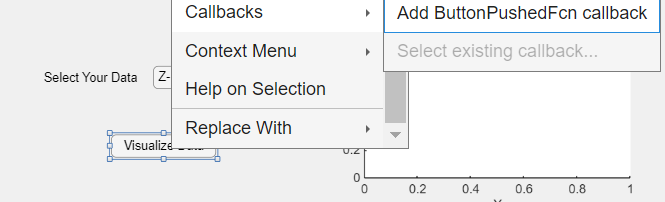

For the button, there is only one type of callback: "ButtonPushedFcn", which executes when the button is pushed. Just like when you added the callback for the drop down, when you add the callback you will automatically be switched to Code View. You should again see a new block of code appear; copy and paste the following code into the new function:

This code will plot `app.CurrentData` on the axes in the app, with time in seconds on the x-axis and amplitude on the y-axis. It also updates the axis labels to reflect these units.

## Test the App!

At this point, the app should be functional! The user should be able to select a data set from the drop down, click "Visualize Data", and see the signal plotted on the axes. To test this out, click the "Run" button in the "Run" section of the toolstrip as shown below:

This will run the app; it should pop up in a new window for you to interact with!

## Add Filtering Functionality

The app now provides the user with the ability to select and visualize a signal of their choice, but there is no filtering functionality! It's time to change that.

### Add New Components

To start, you'll need to add a few new components to your app as follows:

- Add a new Axes component below the existing Axes component (this one will automatically be called `app.UIAxes2`, to differentiate it from the first Axes component you added)

- Add two Edit Field (Numeric) components next to the new Axes component (these will be used to enter the parameters for the desired filter)

- Add another Button component below the Edit Field components (this will be used to apply the filter)

Your app should now look something like this:

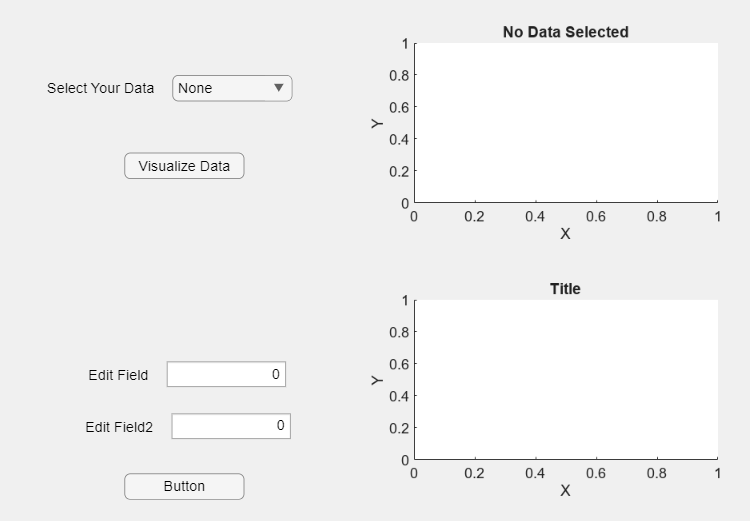

### Edit the New Components

These components will need to be edited the same way the original ones were.

#### The New Axes

To give these axes a more appropriate title, click the new Axes object on the canvas and find the "Title.String" edit field in the Component Browser on the right side of your screen. Change the default title to "No Filter Applied". Similarly to the default title for the above axes, this will be a placeholder until something is plotted on the axes.

#### The Edit Fields

First, the edit fields will need to be renamed to make their purposes clear. By double clicking on the labels, rename the first edit field to "Filter Order" and the second one to "Frame Length". These parameters should sound familiar; they're the parameters used to create a Savitzky-Golay filter, which you learned about in [FilteringIntro.mlx](matlab:open('./FilteringIntro.mlx'))! This app will be applying Savitzky-Golay filters to the two z-axis velocity signals, the same way you did in the script.

In addition to changing the labels of the edit fields, you will also need to change their limits to ensure that the user only inputs reasonable values for the given parameters. To do so, click on the edit field and notice the "Limits" input that appears in the Component Browser:

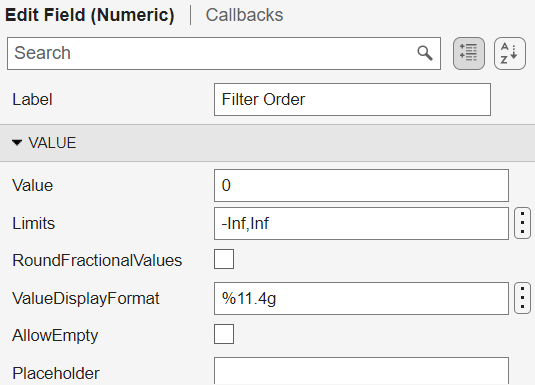

Change the limits of the Filter Order edit field to "1,Inf" because the order of the filter cannot be less than 1. Then, change the limits of the Frame Length edit field to "3,inf" because the frame length must be greater than the filter order and also must be odd.

#### The New Button

To give the button a more appropriate label, double click the button and change the text to "Apply Savitzky-Golay Filter" so that it is clear to the user what the button does.

### Add New Properties

Now that your app has two more pieces of user-inputted data to keep track of, you'll need to create two new properties to store this data. To do this, switch to Code View and scroll to the top of your code to find the Properties section. You should see the five properties you already created; now, create two new ones by adding the following lines of code to the Properties block:

These properties will keep track of the values the user enters into the edit fields. This code sets their default values equal to the minimum values you specified for the edit field components.

### Add Callbacks for the New Components

Just like the existing components, the new components will need callbacks in order to implement their functionality.

#### Add Callbacks for the Edit Fields

Similarly to how the drop down needed a callback in order to update the `app.CurrentData` property, the edit fields will need callbacks to update the `app.FilterOrder` and `app.FrameLength` properties you just created. To add these callbacks, start by right-clicking the Filter Order edit field and selecting "Add ValueChangedFcn callback" from the "Callbacks" menu. As with the other callbacks you've created, this will switch you automatically to Code View. You'll notice that there's already a line of code in the callback, the same way there was when you created the callback for the drop down. Type the following line of code beneath the pre-populated code:

All this does is save the user-specified value from the edit field to the `app.FilterOrder` property. Now, the rest of your callbacks will be able to access this value.

Next, add a callback for the Frame Length edit field the same way you just did for the Filter Order one, but use the following line of code instead:

#### Add a Callback for the New Button

The final piece of functionality you need to implement is to actually apply the filter to the selected signal and plot the results! This will all happen within the callback for the new button. Just like you did for the other button, right click on the "Apply Savitzky-Golay Filter" button and select "Add ButtonPushedFcn callback" from the "Callbacks" menu. Copy and paste the following code into the newly created callback function:

This code does the same thing as the previous button's callback, except that it first applies a Savitzky-Golay filter to `app.CurrentData` using the `sgolayfilt` function, which is a built-in MATLAB function designed for Savitzky-Golay filtering. It then plots the filtered signal on the new axes, adding an appropriate title and axes labels.

## Test Again!

Congratulations! You've now finished building your own filtering app. At this point, it should look something like this:

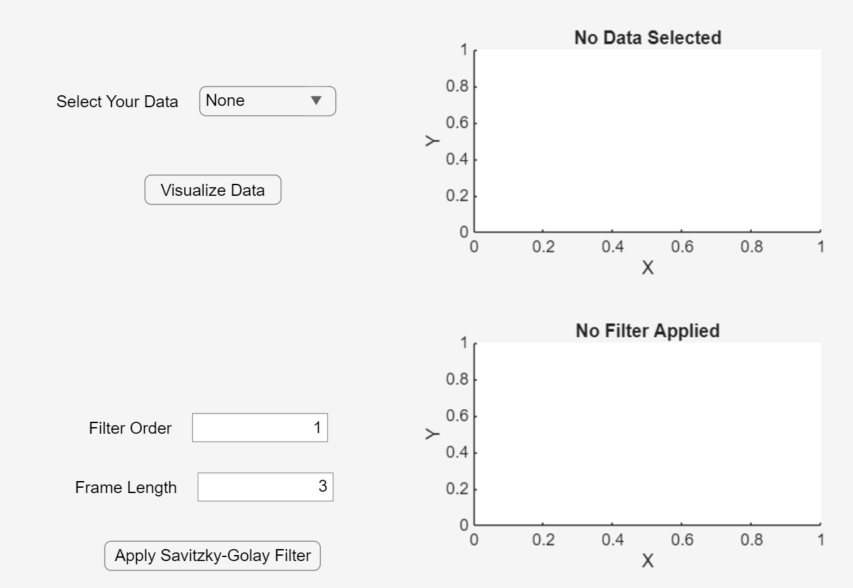

To use the app, click "Run" from the toolstrip like you did before. You should now be able to select a signal, visualize it, and then apply Savitzky-Golay filters with different parameters and visualize the effects of these filters on the signal. 

If you want to reference an example version of the app, use the following button to open it in App Designer:

 
appdesigner("SimpleFilteringApp.mlapp")

  **Pro-tip**. You may notice that this example version of the app has a grid behind it when you look at it in Design View. This allows you to lay out your components on a grid to ensure that they are sized and spaced the way you want them to be. It also ensures that if you make the app larger or smaller, the components will resize along with the app and your layout will be maintained. If you would like to add this to your app, drag a "Grid Layout" component from the "Containers" section of the Component Library onto your app canvas.

## Further Practice

If you would like to explore a more complex filtering app, use the following button to open it in App Designer:

 
appdesigner("FilteringApp.mlapp")

This app builds on the functionality of the app you created by providing the user with more options of signals to load in, more ways to visualize the signals, and more types of filters to apply. It also allows them to visualize both the original signal and the filtered version on the same plot. Feel free to explore these extra components and the code that adds this functionality. If you want, try to add some of this functionality to your own app!